# **Satellite Data Display**

**Hongseok Kim**

## 0. Satellite Initial Orbit Parameter and Simulation Parameter Setting

clear; clc;
addpath('/Users/hongseokkim/Desktop/[Part2]SatelliteAttitudeControlEstimation/')
load("earth_coastline.mat")

Tsim = 5400;
delt = 1;
N = floor(Tsim/delt);
tVec = [0:N-1]' * delt;

%% Define Initial Time
initial_epoch = posixtime(datetime('2024-03-21 00:00:00'));

%% Define Elapsed Days
elapsed_days = 90;

%% Define Current time
current_epoch = initial_epoch + elapsed_days * 24 * 3600;
epoch_datetime = datetime(current_epoch + tVec,'ConvertFrom','posixtime','Format','MM/dd/uuuu HH:mm:ss');
epoch = [epoch_datetime.Year, epoch_datetime.Month, epoch_datetime.Day, epoch_datetime.Hour, epoch_datetime.Minute, epoch_datetime.Second];
disp(epoch_datetime(1))

   06/19/2024 00:00:00




% Orbit Contstant
J2 = 0.00108248;
R_Earth = 6378.1363;
mu = 398600.4415;

%% Define Initial Orbit Parameter
SMA = 6378.1363 + 500; 
ecc = 1e-5;

inc = acos((360/365.2654)/(- 3/2 * J2 * sqrt(mu) * R_Earth^2/(1-ecc)^2/SMA^(7/2) * 3600* 24/pi*180 ))/pi*180

inc = 97.4022

RAAN_0 = 90;
AOP_0 = 0;
theta_0 = 0;
orbit_period = 2*pi* sqrt(SMA^3/mu);


%% Calculate Current Orbit Parameter
d_RAAN_per_day = - 3/2 * J2 * sqrt(mu) * R_Earth^2/(1-ecc)^2/SMA^(7/2) * cos(inc/180*pi) * 3600* 24/pi*180;
d_AOP_Per_day = -3/2 * J2 * sqrt(mu) * R_Earth^2/(1-ecc)^2/SMA^(7/2) * (5/2 * sin(inc/180*pi)^2-2)  * 3600* 24/pi*180;
RAAN = RAAN_0 + d_RAAN_per_day * elapsed_days;
AOP = AOP_0 + d_AOP_Per_day * elapsed_days;
theta = theta_0 + rem(2*pi/orbit_period * elapsed_days * 24 * 3600, 2*pi);


%% Define Sun vector
T = 365.2654;
sun_vector = [cos(2*pi*elapsed_days/T), ...
             sin(2*pi*elapsed_days/T)* cos(23.5/180*pi), ...
             sin(2*pi*elapsed_days/T)* sin(23.5/180*pi)];
disp(sun_vector)

    0.0226    0.9168    0.3986



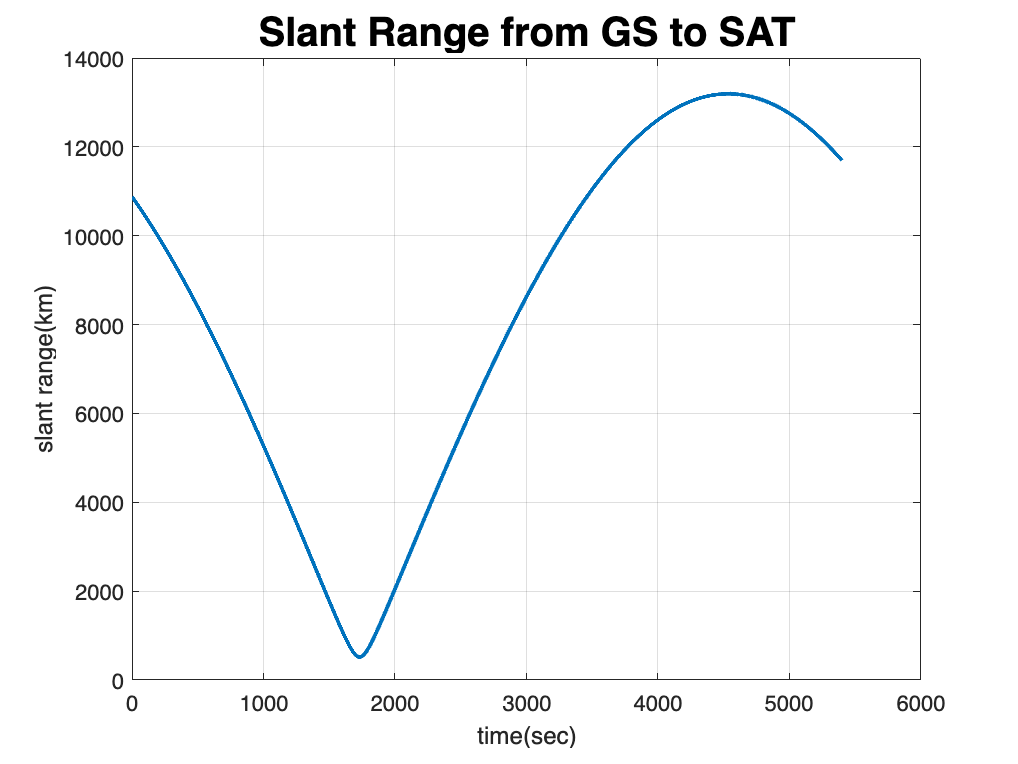


%% Designated Ground Station Location
GS_LLA = [21.4284 87.4145 0];
GS_ECI = zeros(N,3);
for k = 1:N
GS_ECI(k,:) = lla2eci(GS_LLA,epoch(k,:));
end
GS_ECI = GS_ECI/1000;



% Define Initial Orbit Parameter
[r0,v0]=kepler2ijk_hs(SMA,ecc,inc,RAAN,AOP,theta);
[t,y] = j2propagation_hs(r0,v0,tVec);
r = y(:,1:3);
v = y(:,4:6);



slant_range = zeros(N,1);
for i = 1:N
slant_range(i) = norm(GS_ECI(i,:) - r(i,:));
end



% Plot Slant Range
figure;
plot(tVec, slant_range,'LineWidth',2)
title('Slant Range from GS to SAT','FontSize',20,'FontWeight','bold')
grid on
xlabel('time(sec)')
ylabel('slant range(km)')

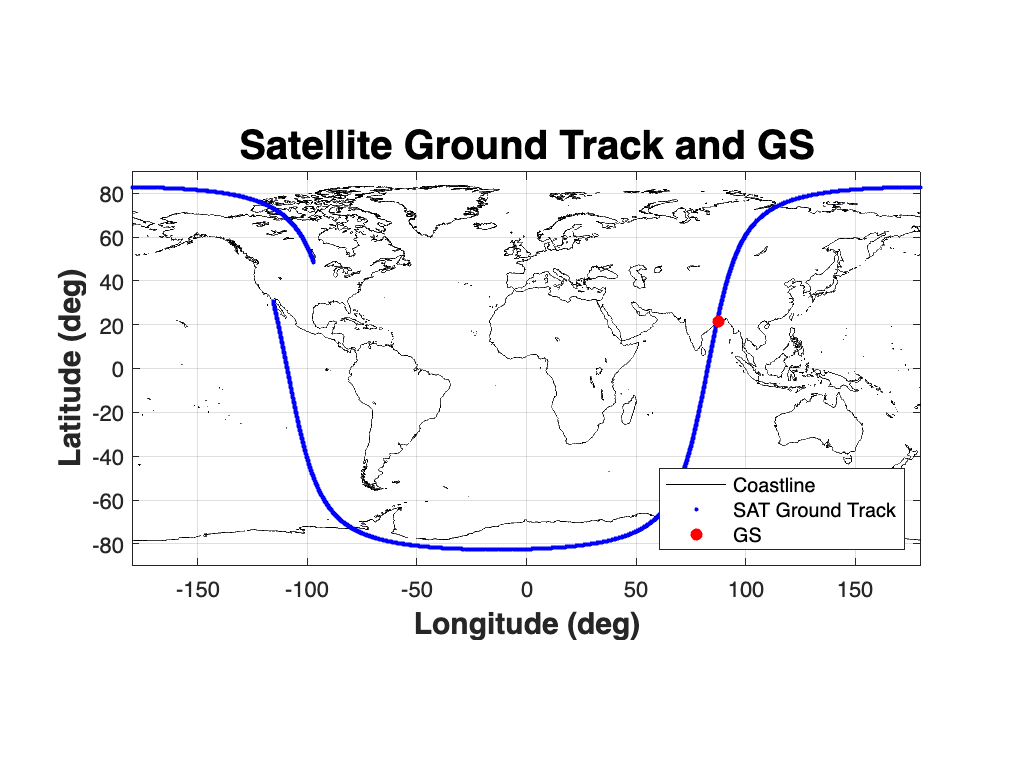



Sat_Ground_Track = eci2lla(r*10^3,epoch);

% Plot orbit trajectory and GS Location
figure;
plot(earth_coastline(:,1),earth_coastline(:,2),'k')
hold on
scatter(Sat_Ground_Track(:,2), Sat_Ground_Track(:,1),'b','.')
scatter(GS_LLA(2) ,GS_LLA(1),'red','filled')
legend('Coastline','SAT Ground Track','GS','Location','southeast')
hold off
axis equal
xlim([-180,180])
ylim([-90,90])
grid on
title('Satellite Ground Track and GS','FontSize',20,'FontWeight','bold')
ylabel('Latitude (deg)','FontSize',15,'FontWeight','bold')
xlabel('Longitude (deg)','FontSize',15,'FontWeight','bold')
grid on



% Define Oversampe Factor
oversampFact = 10;



n = length(tVec);
% Total Mode Definition Length
disp(n)

        5400




% Mission Planning
operation_mode_vec = 1* ones(n,1);


% initial operation mode
initial_operation_mode = 1;
% 1: Nadir Pointing Mode
% 2: Energy Transmission Mode
% 3: Sun Pointing Mode

operation_mode_vec(1:850) = 3;
operation_mode_vec(851:1150) = 1;
operation_mode_vec(1151:2000) = 2;
operation_mode_vec(2001:2200) = 1;
operation_mode_vec(2201:end) = 3;



run('SAT_Control_Simulate.m')

### III.0 Bata Angle Calculation

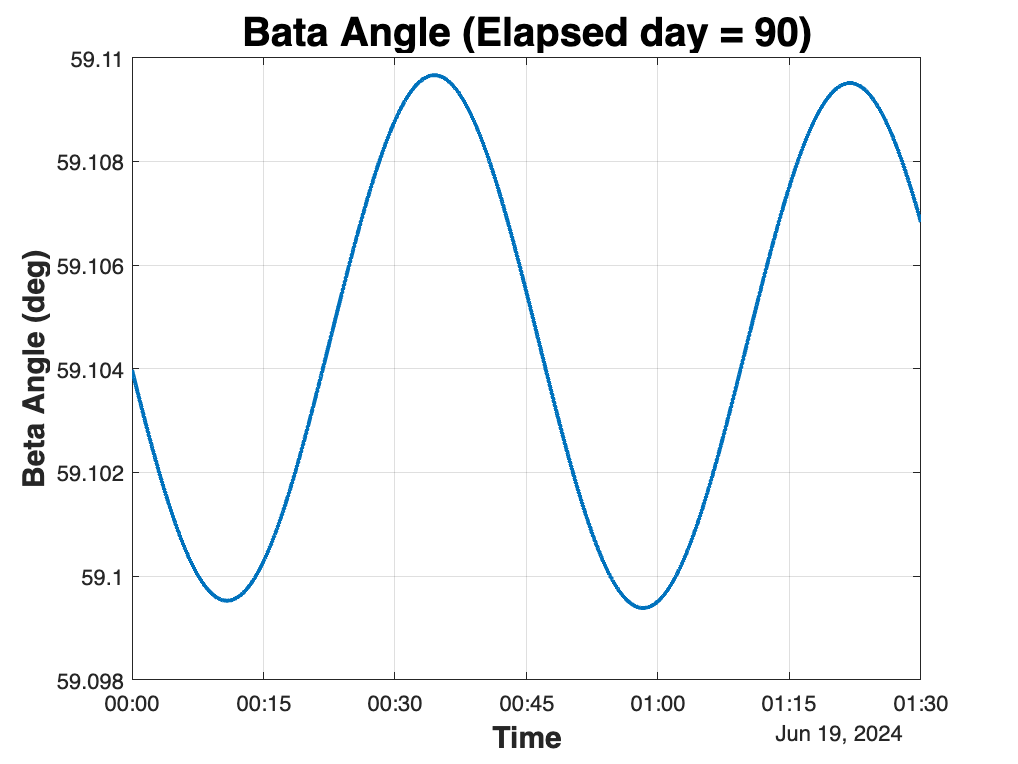

beta_Angle = zeros(length(Q.state.hMat(:,1)),1);

for i = 1:length(-Q.state.hMat(:,1))
beta_Angle(i) = 90 - acos(dot(Q.state.hMat(i,:), sun_vector)/norm(Q.state.hMat(i,:)/norm(sun_vector)))/pi*180;
end


simulation_epoch_datetime = datetime(current_epoch + Q.tVec,'ConvertFrom','posixtime','Format','MM/dd/uuuu HH:mm:ss');

plot(simulation_epoch_datetime, beta_Angle,'LineWidth',2)
grid on;
title('Bata Angle (Elapsed day = 90)','FontSize',20,'FontWeight','bold')
xlabel('Time','FontSize',15,'FontWeight','bold')
ylabel('Beta Angle (deg)','FontSize',15,'FontWeight','bold')

### III.1 Satellite Trajectory with Body Axis Vector Display

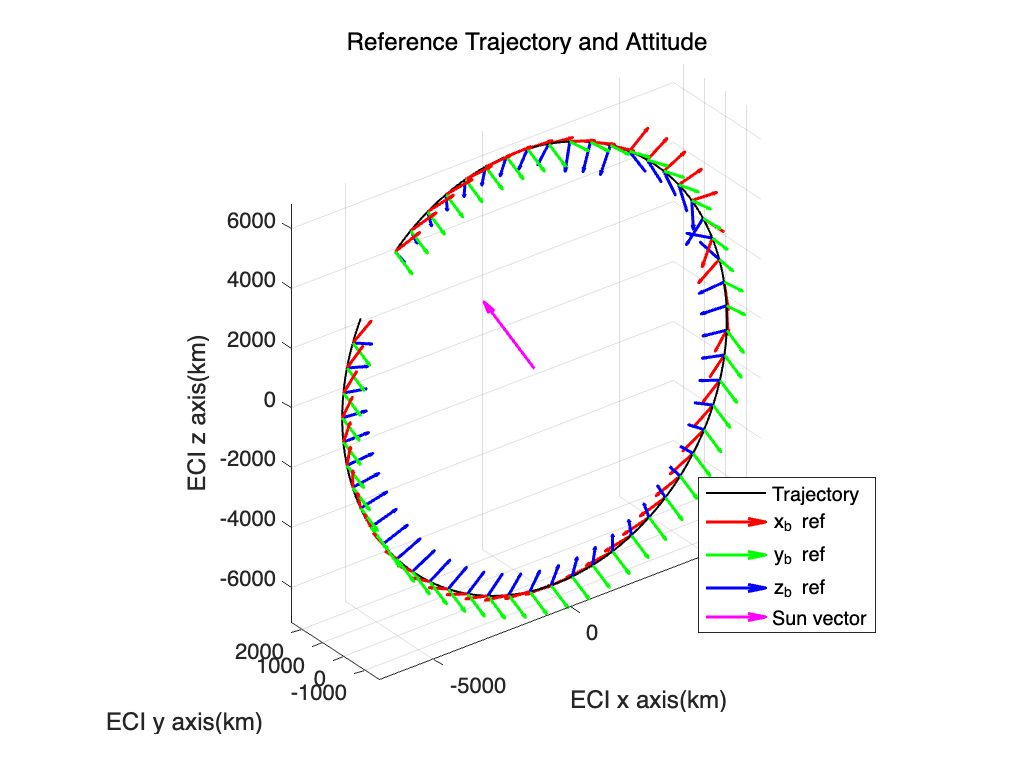

% Reference Trajectory and Attitude

figure;

plot3(r(:,1), r(:,2), r(:,3),'Color','k','LineWidth',1)
hold on;
grid on;
axis equal;
title('Reference Trajectory and Attitude')
xlabel('ECI x axis(km)')
ylabel('ECI y axis(km)')
zlabel('ECI z axis(km)')

hold on
scalefactor = 1000;
xdir = scalefactor * xIstar;
ydir = scalefactor * yIstar;
zdir = scalefactor * zIstar;
arrowLineWidth = 1.5;



for i = 1:100:length(tVec)
  startPos = r(i,1:3);

  quiver3(startPos(1), startPos(2), startPos(3),xdir(i,1),xdir(i,2),xdir(i,3),...
      'Color', 'r', 'Linewidth',arrowLineWidth, 'MaxHeadSize', 0.5)
  quiver3(startPos(1), startPos(2), startPos(3),ydir(i,1),ydir(i,2),ydir(i,3),...
      'Color', 'g', 'Linewidth',arrowLineWidth, 'MaxHeadSize', 0.5)
  quiver3(startPos(1), startPos(2), startPos(3),zdir(i,1),zdir(i,2),zdir(i,3),...
      'Color', 'b', 'Linewidth',arrowLineWidth, 'MaxHeadSize', 0.5)
  quiver3(0,0,0,3000*sun_vector(1),3000*sun_vector(2),3000*sun_vector(3),...
      'Color','m','Linewidth',arrowLineWidth, 'MaxHeadSize', 0.5)
end

hold off;
legend('Trajectory','x_b ref','y_b ref','z_b ref','Sun vector')

legend("Position", [0.17506,0.13938,0.15179,0.15595])

legend("Position", [0.69763,0.19517,0.15179,0.15595])

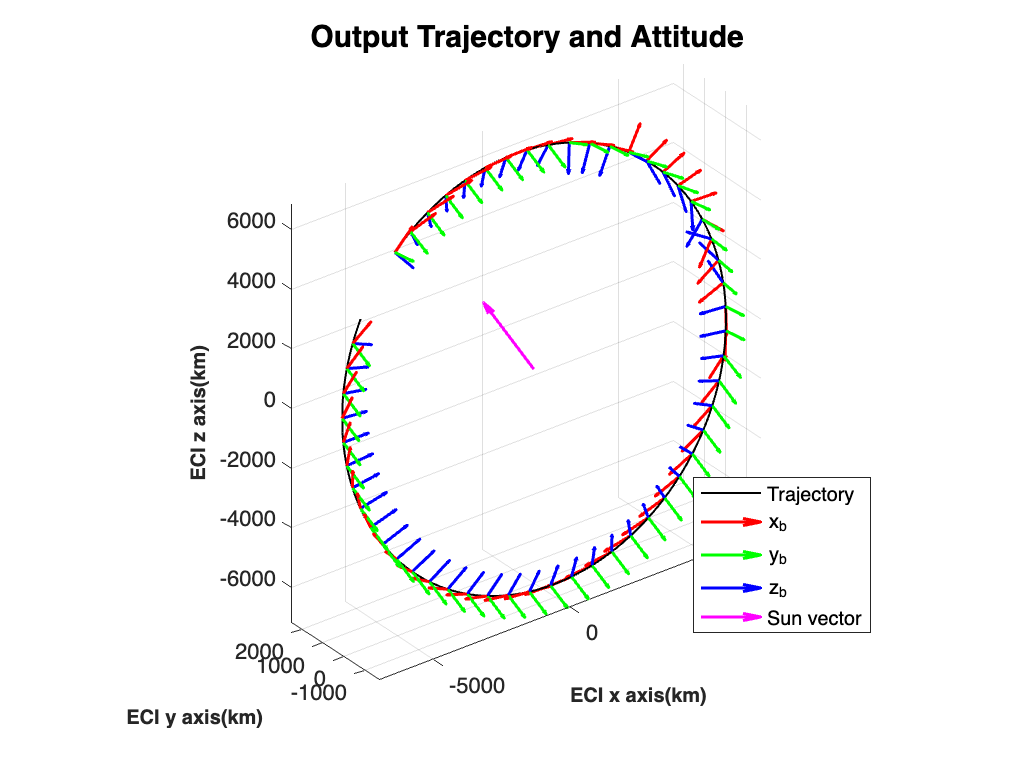



% Output Trajectory and Attitude

figure;

plot3(Q.state.rMat(:,1), Q.state.rMat(:,2), Q.state.rMat(:,3),'Color','k','LineWidth',1)
hold on;
grid on;
axis equal;
title('Output Trajectory and Attitude','FontSize',15,'FontWeight','bold')
xlabel('ECI x axis(km)','FontSize',10,'FontWeight','bold')
ylabel('ECI y axis(km)','FontSize',10,'FontWeight','bold')
zlabel('ECI z axis(km)','FontSize',10,'FontWeight','bold')

hold on
scalefactor = 1000;
xdir = scalefactor * Q.state.xIMat;
ydir = scalefactor * Q.state.yIMat;
zdir = scalefactor * Q.state.zIMat;
arrowLineWidth = 1.5;



for i = 1:1000:length(Q.tVec)
  startPos = Q.state.rMat(i,1:3);

  quiver3(startPos(1), startPos(2), startPos(3),xdir(i,1),xdir(i,2),xdir(i,3),...
      'Color', 'r', 'Linewidth',arrowLineWidth, 'MaxHeadSize', 0.5)
  quiver3(startPos(1), startPos(2), startPos(3),ydir(i,1),ydir(i,2),ydir(i,3),...
      'Color', 'g', 'Linewidth',arrowLineWidth, 'MaxHeadSize', 0.5)
  quiver3(startPos(1), startPos(2), startPos(3),zdir(i,1),zdir(i,2),zdir(i,3),...
      'Color', 'b', 'Linewidth',arrowLineWidth, 'MaxHeadSize', 0.5)
  quiver3(0,0,0,3000*sun_vector(1),3000*sun_vector(2),3000*sun_vector(3),...
      'Color','m','Linewidth',arrowLineWidth, 'MaxHeadSize', 0.5)
end

hold off;
legend('Trajectory','x_b','y_b','z_b','Sun vector')

legend("Position", [0.18054,0.12217,0.15179,0.15595])

legend("Position", [0.6927,0.19606,0.15179,0.15595])

## III.1.1 Body Axis Vector Comparison

Nadir Mode: z axis compare

GS contact Mode: z axis compare

Sun Pointing Mode: y axis compare

## III.2 Satellite Euler Angle (Roll, Pitch, Yaw) display

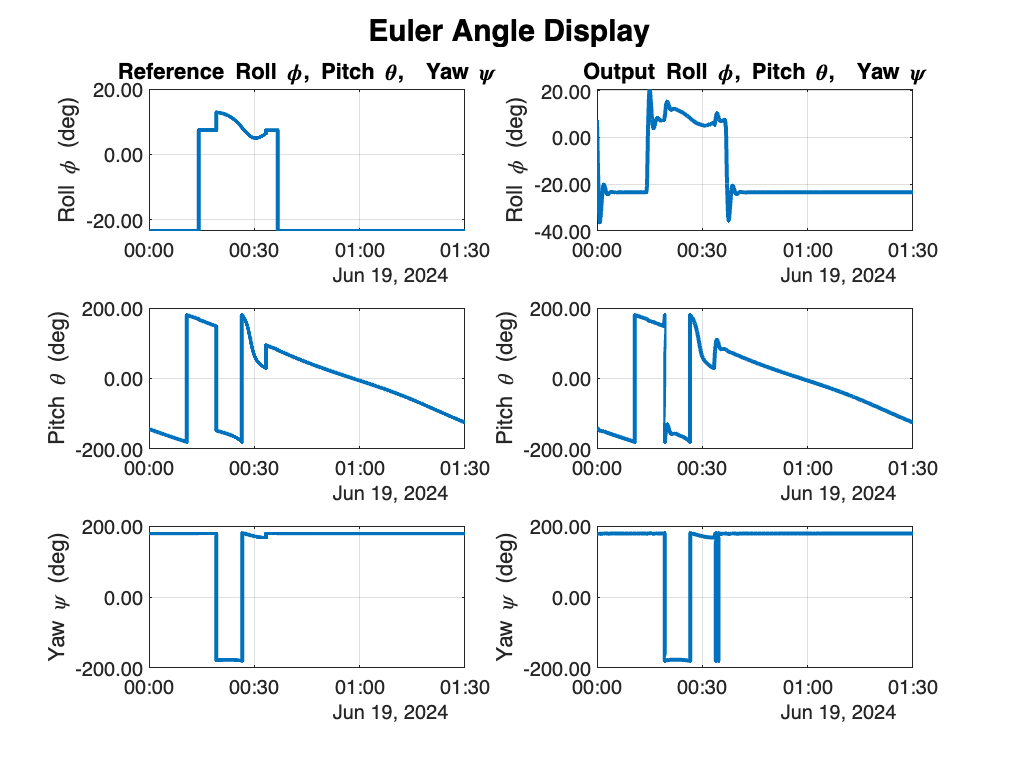

figure;
sgtitle('Euler Angle Display','FontSize',15,'FontWeight','bold')

reference_epoch_datetime = datetime(current_epoch + tVec,'ConvertFrom','posixtime','Format','MM/dd/uuuu HH:mm:ss');

output_epoch_datetime = datetime(current_epoch + Q.tVec,'ConvertFrom','posixtime','Format','MM/dd/uuuu HH:mm:ss');



subplot(3,2,1)
plot(reference_epoch_datetime,e_star(:,1)/pi*180,'LineWidth',2)
ylabel('Roll \phi (deg)')
ytickformat('%.2f')
title('Reference Roll \phi, Pitch \theta,  Yaw \psi','FontWeight','bold')
grid on

subplot(3,2,2)
plot(output_epoch_datetime,Q.state.eMat(:,1)/pi*180,'LineWidth',2)
ylabel('Roll \phi (deg)')
ytickformat('%.2f')
title('Output Roll \phi, Pitch \theta,  Yaw \psi','FontWeight','bold')
grid on


subplot(3,2,3)
plot(reference_epoch_datetime,e_star(:,2)/pi*180,'LineWidth',2)
ylabel('Pitch \theta (deg)')
ytickformat('%.2f')
grid on

subplot(3,2,4)
plot(output_epoch_datetime,Q.state.eMat(:,2)/pi*180,'LineWidth',2)
ylabel('Pitch \theta (deg)')
ytickformat('%.2f')
grid on

subplot(3,2,5)
plot(reference_epoch_datetime,e_star(:,3)/pi*180,'LineWidth',2)
ylabel('Yaw \psi (deg)')
ytickformat('%.2f')
grid on

subplot(3,2,6)
plot(output_epoch_datetime,Q.state.eMat(:,3)/pi*180,'LineWidth',2)
ylabel('Yaw \psi (deg)')
ytickformat('%.2f')
grid on

### III.3 Reaction Wheel Angular Rate Display

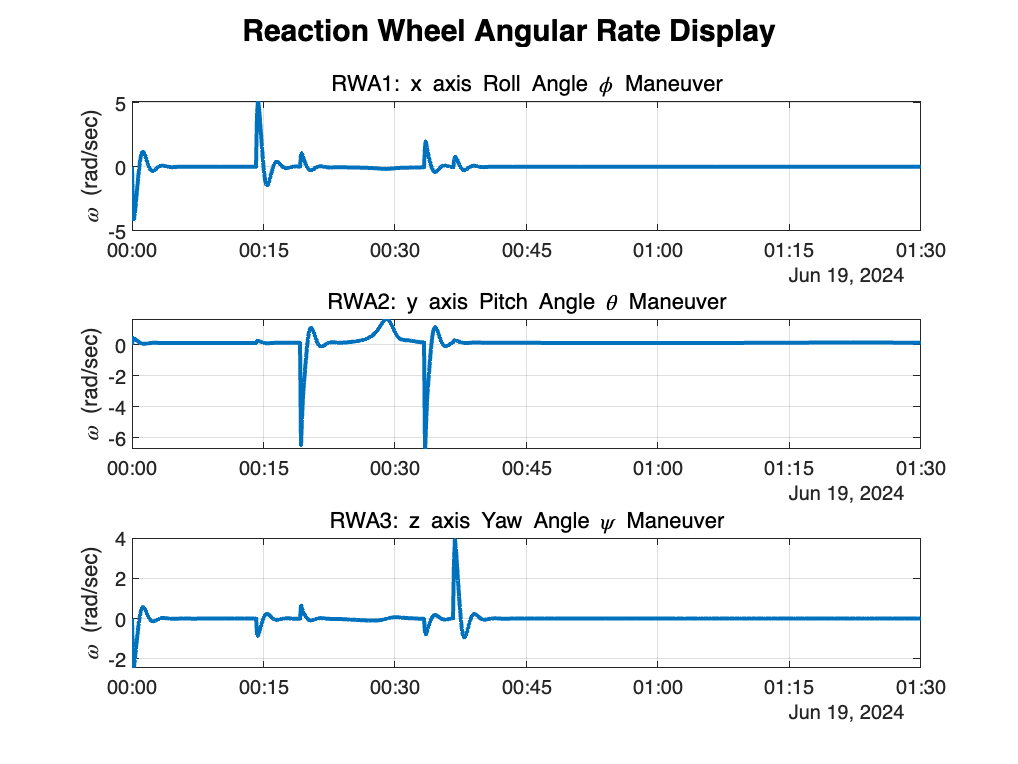

figure;

output_epoch_datetime = datetime(current_epoch + Q.tVec,'ConvertFrom','posixtime','Format','MM/dd/uuuu HH:mm:ss');

sgtitle('Reaction Wheel Angular Rate Display','FontSize',15,'FontWeight','bold')

subplot(3,1,1)
plot(output_epoch_datetime,Q.state.omegaVecMat(:,1),'LineWidth',2)
title('RWA1: x axis Roll Angle \phi Maneuver')
ylabel('\omega (rad/sec)')
grid on

subplot(3,1,2)
plot(output_epoch_datetime,Q.state.omegaVecMat(:,2),'LineWidth',2)
title('RWA2: y axis Pitch Angle \theta Maneuver')
ylabel('\omega (rad/sec)')
grid on

subplot(3,1,3)
plot(output_epoch_datetime,Q.state.omegaVecMat(:,3),'LineWidth',2)
title('RWA3: z axis Yaw Angle \psi Maneuver')
ylabel('\omega (rad/sec)')
grid on

### III.4 Reaction Wheel Voltage Display

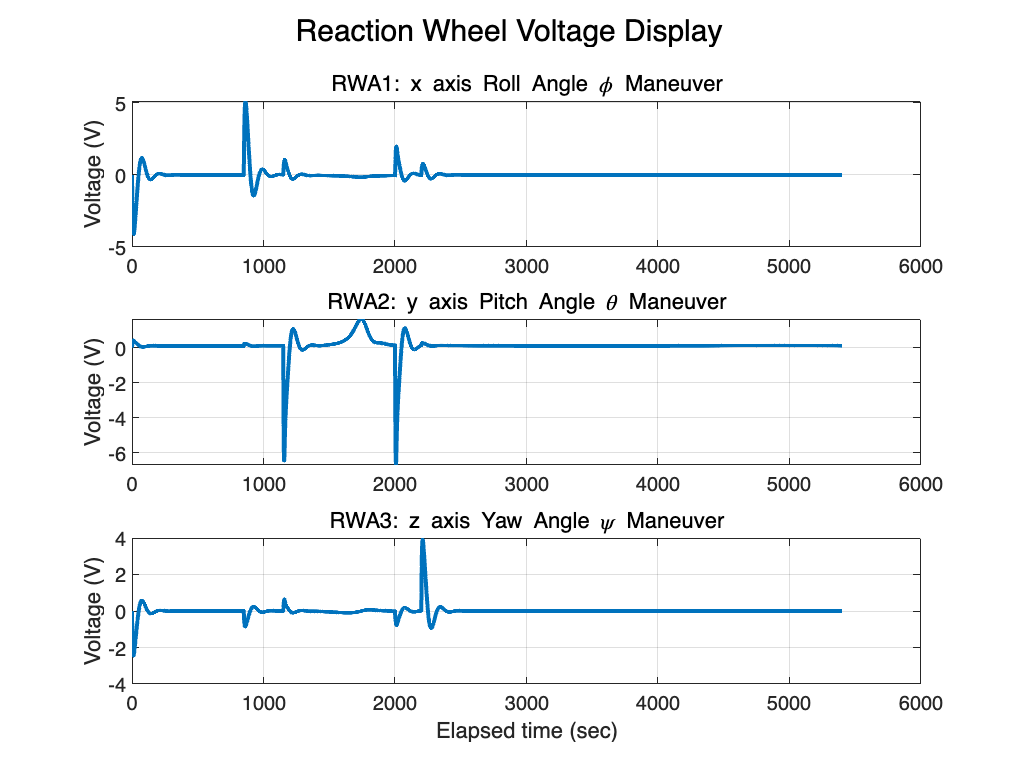

figure;
sgtitle('Reaction Wheel Voltage Display')

subplot(3,1,1)
plot(tVec,Q.state.eaMat(:,1),'LineWidth',2)
title('RWA1: x axis Roll Angle \phi Maneuver')
ylabel('Voltage (V)')
grid on

subplot(3,1,2)
plot(tVec,Q.state.eaMat(:,2),'LineWidth',2)
title('RWA2: y axis Pitch Angle \theta Maneuver')
ylabel('Voltage (V)')
grid on

subplot(3,1,3)
plot(tVec,Q.state.eaMat(:,3),'LineWidth',2)
title('RWA3: z axis Yaw Angle \psi Maneuver')
ylabel('Voltage (V)')
xlabel('Elapsed time (sec)')
grid on

**III.5 Reaction Wheel Voltage Display**

## **IV. **$\textrm{Using}\;{\mathit{\mathbf{Z}}}_{\mathit{\mathbf{I}}} ,{\mathit{\mathbf{r}}}_{\mathit{\mathbf{I}}} \Rightarrow \textrm{Ground}\;\textrm{Pointing}\;\textrm{Location}$


$$\begin{array}{l}
\textrm{Given}:\vec{{\mathit{\mathbf{r}}}_I } ,\;\vec{{\mathit{\mathbf{z}}}_I } \;\\
\textrm{Want}:\;\vec{{\mathit{\mathbf{G}}}_I } \;\textrm{ECI}\;\textrm{vector}\;\textrm{of}\;\textrm{Ground}\;\textrm{Pointing}\;\textrm{Location}\\
\textrm{Assumption}:\textrm{Earth}\;\textrm{is}\;\textrm{Perfect}\;\textrm{Sphere}\;\textrm{with}\;\textrm{radius}\;6378\textrm{km}
\end{array}$$


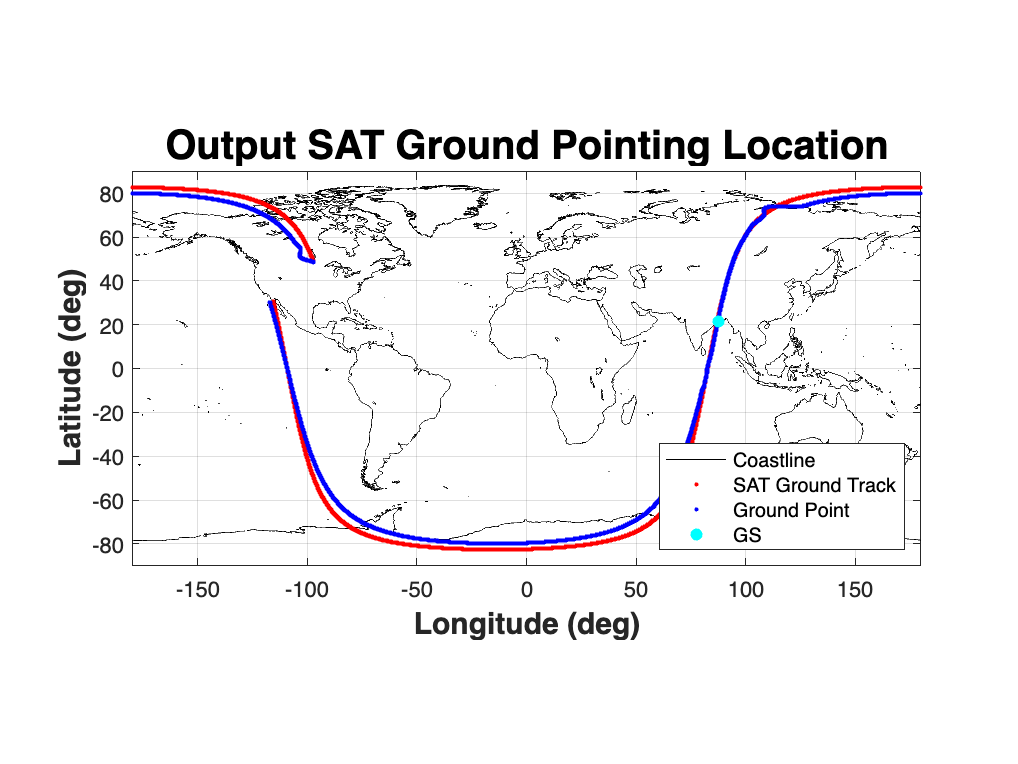

figure;
epoch_output_datetime = datetime(current_epoch + Q.tVec,'ConvertFrom','posixtime','Format','MM/dd/uuuu HH:mm:ss');
epoch_output = [epoch_output_datetime.Year, ...
                epoch_output_datetime.Month, ...
                epoch_output_datetime.Day, ...
                epoch_output_datetime.Hour, ...
                epoch_output_datetime.Minute, ...
                epoch_output_datetime.Second];


Ground_Pointing_ECI = zeros(length(Q.tVec),3);
off_Nadir_Angle = zeros(length(Q.tVec),1);
beta_Angle = zeros(length(Q.tVec),1);

for i = 1:length(Q.tVec)

    z_I = Q.state.zIMat(i,:)';
    r_I = Q.state.rMat(i,:)';

    OA = norm(r_I);
    OB = 6378.1363;

    theta = acos(dot(-r_I, z_I)/norm(r_I)/norm(z_I));

    if norm(dot(-r_I, z_I)/norm(r_I)/norm(z_I)-1) <10e-10
    theta = 0;
    end

    off_Nadir_Angle(i) = theta/pi*180;

    beta = real(pi - asin(sin(theta) * OA/OB));
    beta_Angle(i) = beta/pi*180;

    alpha = pi() - theta - beta;


    if alpha > pi/2
        alpha = pi - alpha;
    end

    AB = sin(alpha)/sin(beta) * OA;

    if alpha < 10e-5
    AB = OA - OB;
    end

    G_I = AB * z_I;
    Ground_Pointing_ECI(i,:) = r_I' + G_I';

end
% figure;
% plot(Q.tVec, off_Nadir_Angle)
% 
% figure;
% plot(Q.tVec, beta_Angle)

Ground_Pointing_LLA_real = eci2lla(Ground_Pointing_ECI*10^3,epoch_output);
Sat_Ground_Track = eci2lla(Q.state.rMat*10^3,epoch_output);

figure;
plot(earth_coastline(:,1),earth_coastline(:,2),'k')
hold on
scatter(Sat_Ground_Track(:,2),Sat_Ground_Track(:,1),'r','.')
scatter(Ground_Pointing_LLA_real(:,2),Ground_Pointing_LLA_real(:,1),'b','.')
scatter(GS_LLA(2) ,GS_LLA(1),'cyan','filled')
legend('Coastline','SAT Ground Track','Ground Point','GS','Location','southeast')
hold off
axis equal
xlim([-180,180])
ylim([-90,90])
grid on
title('Output SAT Ground Pointing Location','FontSize',20,'FontWeight','bold')
ylabel('Latitude (deg)','FontSize',15,'FontWeight','bold')
xlabel('Longitude (deg)','FontSize',15,'FontWeight','bold')
grid on



% plot(Q.tVec,Ground_Pointing_LLA_real(:,1))
% plot(Q.tVec,Ground_Pointing_LLA_real(:,2))

## V. Satellite Ground Pointing Location in Lattitude and Logitude

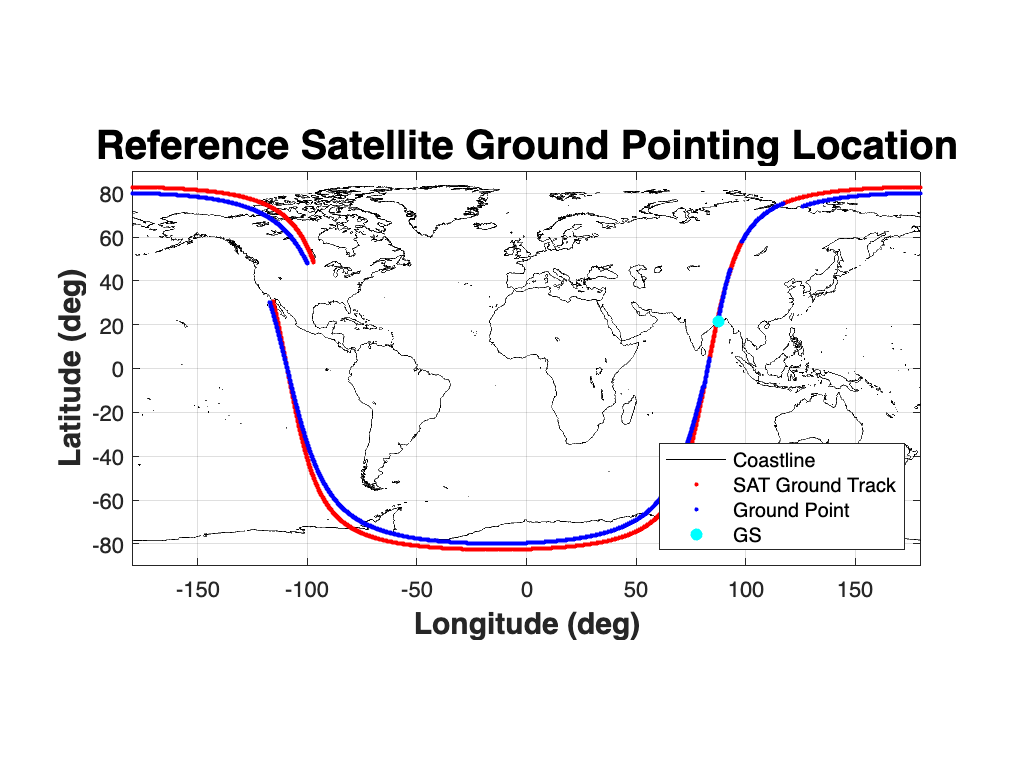

% % Initial epoch
Ground_Pointing_ECI = zeros(length(tVec),3);
off_Nadir_Angle = zeros(length(tVec),1);
beta_Angle = zeros(length(tVec),1);

n = length(tVec);



for i = 1:length(tVec)

    z_I = zIstar(i,:)';
    r_I = r(i,:)';

    OA = norm(r_I);
    OB = 6378.1363;

    theta = acos(dot(-r_I, z_I)/norm(r_I)/norm(z_I));

    if norm(dot(-r_I, z_I)/norm(r_I)/norm(z_I)-1) <10e-10
    theta = 0;
    end

    off_Nadir_Angle(i) = theta/pi*180;
    beta = real(pi - asin(sin(theta) * OA/OB));
    beta_Angle(i) = beta/pi*180;

    alpha = pi() - theta - beta;


    if alpha > pi/2
        alpha = pi - alpha;
    end

    AB = sin(alpha)/sin(beta) * OA;

    if alpha < 10e-5
    AB = OA - OB;
    end

    G_I = AB * z_I;
    Ground_Pointing_ECI(i,:) = r_I' + G_I';

end

% plot(tVec, off_Nadir_Angle)
% plot(tVec, beta_Angle)
Ground_Pointing_LLA = eci2lla(Ground_Pointing_ECI*10^3,epoch);
Sat_Ground_Track = eci2lla(r*10^3,epoch);

plot(earth_coastline(:,1),earth_coastline(:,2),'k')
hold on
scatter(Sat_Ground_Track(:,2),Sat_Ground_Track(:,1),'r','.')
scatter(Ground_Pointing_LLA(:,2),Ground_Pointing_LLA(:,1),'b','.')
scatter(GS_LLA(2) ,GS_LLA(1),'cyan','filled')
legend('Coastline','SAT Ground Track','Ground Point','GS','Location','southeast')
hold off
axis equal
xlim([-180,180])
ylim([-90,90])
grid on
title('Reference Satellite Ground Pointing Location','FontSize',20,'FontWeight','bold')
ylabel('Latitude (deg)','FontSize',15,'FontWeight','bold')
xlabel('Longitude (deg)','FontSize',15,'FontWeight','bold')
grid on

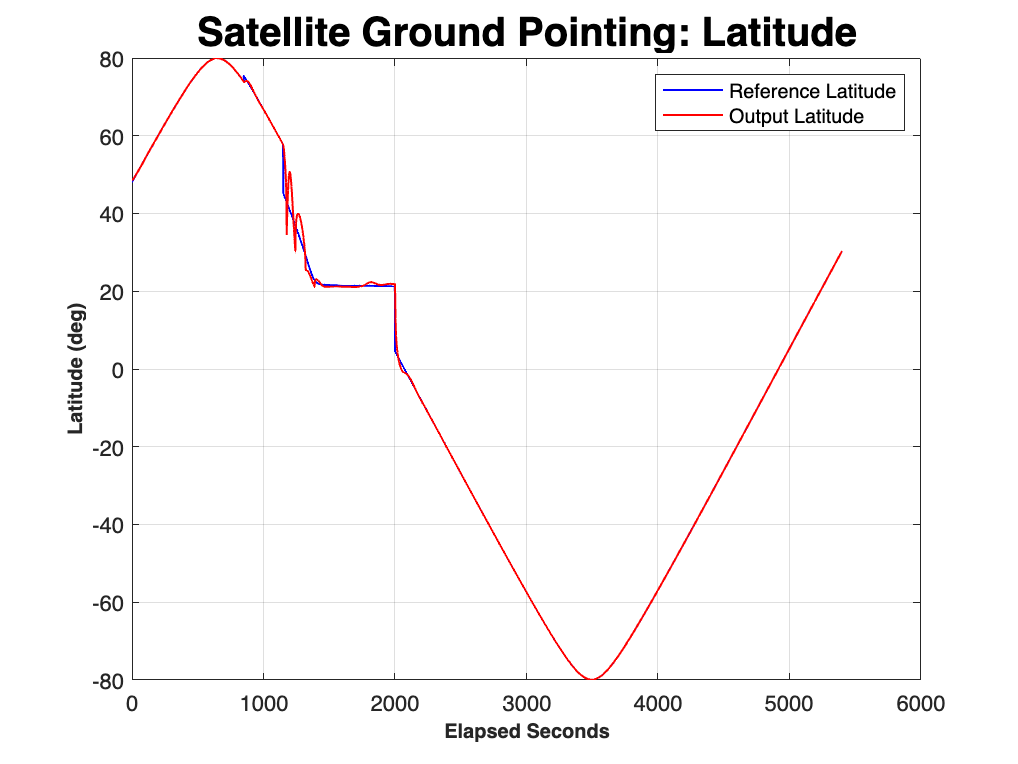



figure;
plot(tVec,Ground_Pointing_LLA(:,1),'b','LineWidth',1)
title('Satellite Ground Pointing: Latitude','FontSize',20,'FontWeight','bold')
hold on
plot(Q.tVec,Ground_Pointing_LLA_real(:,1),'r','LineWidth',1)
legend('Reference Latitude','Output Latitude')
grid on
xlabel('Elapsed Seconds','FontSize',10,'FontWeight','bold')
ylabel('Latitude (deg)','FontSize',10,'FontWeight','bold')
hold off

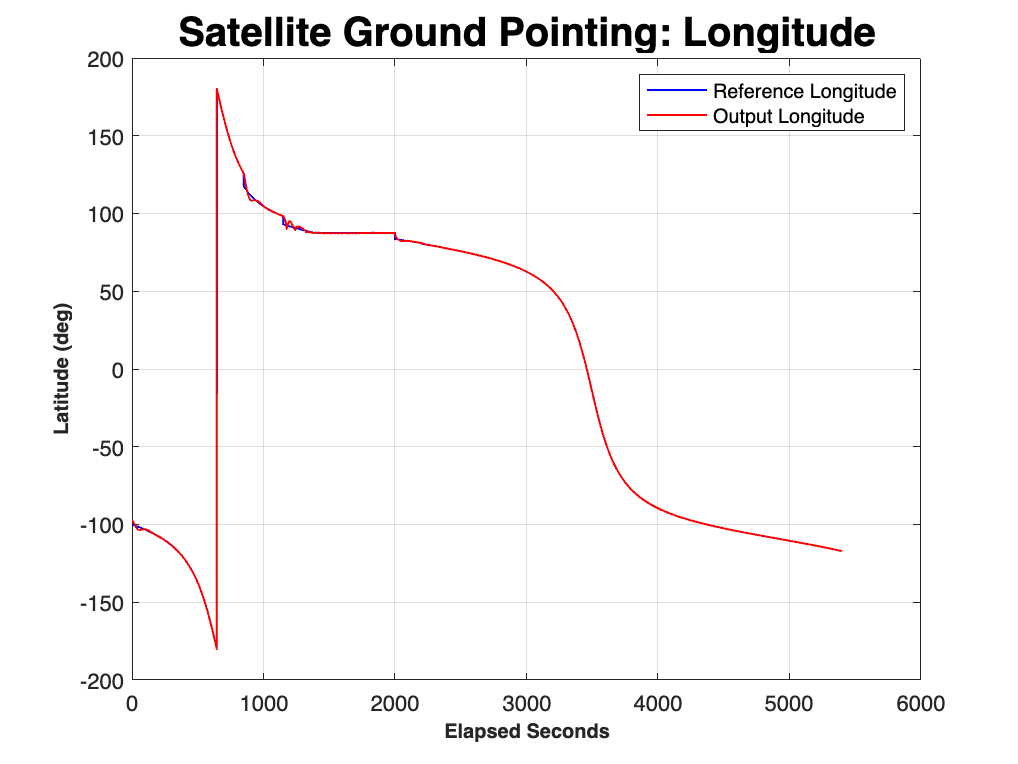


figure;

plot(tVec,Ground_Pointing_LLA(:,2),'b','LineWidth',1)
title('Satellite Ground Pointing: Longitude','FontSize',20,'FontWeight','bold')
hold on
plot(Q.tVec,Ground_Pointing_LLA_real(:,2),'r','LineWidth',1)
legend('Reference Longitude','Output Longitude')
grid on
xlabel('Elapsed Seconds','FontSize',10,'FontWeight','bold')
ylabel('Latitude (deg)','FontSize',10,'FontWeight','bold')
hold off


clear all;